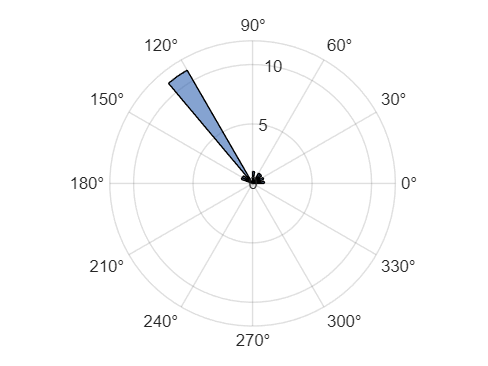

% Leer datos
datos = readtable('C:\Users\56931\Desktop\Proyecto\Resultados\parametros_morfometricos_final.xlsx');

% Elegir azimut a graficar
azimuts = datos.Crater_Azimuth;  % O cambia a Crater_Azimuth

% Eliminar NaN
azimuts = azimuts(~isnan(azimuts));

% Convertir a radianes
azimuts_rad = deg2rad(azimuts);

% Configurar número de sectores (e.g. 10°)
n_sectores = 36; % 360° / 10°
edges = linspace(0, 2*pi, n_sectores+1);

% Graficar rosa
figure;
polarhistogram(azimuts_rad, edges, 'FaceColor', [0.2 0.4 0.7], 'EdgeColor', 'k');
title('Rosa de orientación - Eje mayor de la base del cono');

% Guardar figura
saveas(gcf, 'C:\Users\56931\Desktop\Proyecto\Graficos\rosa_orientacion_Crater.png');